# Redes Neuronales convolucionales.

clc
close all
clearvars

E1 = [255 255 255 255 ;255  0   0   0   ; 255 0   0   0   ;255  255 255 255]; 
E2 = [255 255 255 255 ; 0   0   255 0   ; 0   0   255 0   ; 0   0   255 0  ] ; 
E3 = [255 0   0   255 ; 255 0   0   255 ; 255 0   0   255 ; 0   255 255 0  ] ;
E4 = [0   255 0   0   ; 0   255 0   0   ; 0   255 0   0   ; 255 255 255 255] ;


## **Definimos los kernels.**

k1 = [ 0  1  0 ;  1  4 -1 ;  0  1  0]; % Laplaciano
k2 = [ 1  1  1 ;  1 -2  1 ; -1 -1 -1]; % Norte
k3 = [-1  1  1 ; -1 -2  1 ; -1  1  1]; % Este
k4 = [ 1  2  1 ;  0  0  0 ; -1 -2 -1]; % Sobel C
k5 = [-1  0  1 ; -2  0  2 ;  1  0  1]; % Sobel F

## **Ajustamos los bordes de la imagenes de entrada**

I1 = bordes_imagen(E1, 6);
I2 = bordes_imagen(E2, 6);
I3 = bordes_imagen(E3, 6);
I4 = bordes_imagen(E4, 6);

## **Convolucion 2D**

conv2(I1,k1,'valid');
im1 = convolucion(I1, k1, 4);
im2 = convolucion(I1, k2, 4);
im3 = convolucion(I1, k3, 4);
im4 = convolucion(I1, k4, 4);
im5 = convolucion(I1, k5, 4);


## **Subsamplig - pooling 2D**

P1 = pooling(im1,2,4);
P2 = pooling(im2,2,4);
P3 = pooling(im3,2,4);
P4 = pooling(im4,2,4);
P5 = pooling(im5,2,4);

## **Interconexion red neuronal.**

DI1 = interconexion(P1, P2, P3, P4, P5,2);

## **Convolucion 2D**

im1 = convolucion(I2, k1, 4);
im2 = convolucion(I2, k2, 4);
im3 = convolucion(I2, k3, 4);
im4 = convolucion(I2, k4, 4);
im5 = convolucion(I2, k5, 4);

## **Subsamplig - pooling 2D**

P1 = pooling(im1,2,4);
P2 = pooling(im2,2,4);
P3 = pooling(im3,2,4);
P4 = pooling(im4,2,4);
P5 = pooling(im5,2,4);

## **Interconexion red neuronal.**

DI2 = interconexion(P1, P2, P3, P4, P5,2);

## **Convolucion 2D**

im1 = convolucion(I3, k1, 4);
im2 = convolucion(I3, k2, 4);
im3 = convolucion(I3, k3, 4);
im4 = convolucion(I3, k4, 4);
im5 = convolucion(I3, k5, 4);

## **Subsamplig - pooling 2D**

P1 = pooling(im1,2,4);
P2 = pooling(im2,2,4);
P3 = pooling(im3,2,4);
P4 = pooling(im4,2,4);
P5 = pooling(im5,2,4);

## **Interconexion red neuronal.**

DI3 = interconexion(P1, P2, P3, P4, P5,2);

## **Convolucion 2D**

im1 = convolucion(I4, k1, 4);
im2 = convolucion(I4, k2, 4);
im3 = convolucion(I4, k3, 4);
im4 = convolucion(I4, k4, 4);
im5 = convolucion(I4, k5, 4);

## **Subsamplig - pooling 2D**

P1 = pooling(im1,2,4);
P2 = pooling(im2,2,4);
P3 = pooling(im3,2,4);
P4 = pooling(im4,2,4);
P5 = pooling(im5,2,4);

## **Interconexion red neuronal.**

DI4 = interconexion(P1, P2, P3, P4, P5,2);


## INICIAMOS EL ENTRENAMITO DE LA CAPA

Definimos los patrones de entrada a entrenar


x = [DI1' DI2' DI3' DI4' DI1' DI2' DI3' DI4' DI1' DI2' DI3' DI4']

x =         1275         701        1020         765        1275         701        1020         765        1275         701        1020         765
         765        1211         638         128         765        1211         638         128         765        1211         638         128
        1275           0         765        1084        1275           0         765        1084        1275           0         765        1084
         765         893         765         829         765         893         765         829         765         893         765         829
         383         701         128         128         383         701         128         128         383         701         128         128
         765         446         128         128         765         446         128         128         765         446         128         128
           0         128         128           0           0         128         128           0           0         128      

Definimos las salidas deseadas para cada patron

sd = [ 10  0  0  0 10  0  0  0 10  0  0  0 
        0 10  0  0  0 10  0  0  0 10  0  0 
        0  0 10  0  0  0 10  0  0  0 10  0
        0  0  0 10  0  0  0 10  0  0  0 10 ]

sd =     10     0     0     0    10     0     0     0    10     0     0     0
     0    10     0     0     0    10     0     0     0    10     0     0
     0     0    10     0     0     0    10     0     0     0    10     0
     0     0     0    10     0     0     0    10     0     0     0    10


Definimos las salidas deseadas para cada patron

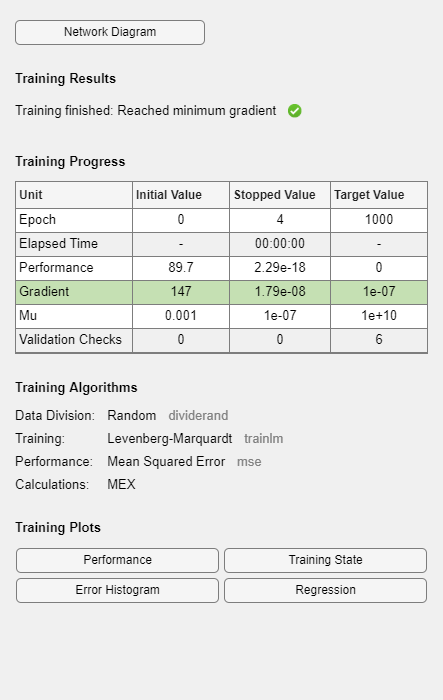

net = feedforwardnet(20); 
net = configure(net,x,sd);

net = train(net,x,sd);

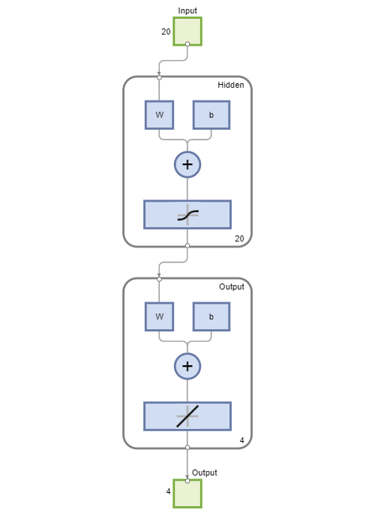

view(net);

y = net(x)

y =    10.0000    0.0000   -0.0000   -0.0000   10.0000    0.0000   -0.0000   -0.0000   10.0000    0.0000   -0.0000   -0.0000
    0.0000   10.0000    0.0000    0.0000    0.0000   10.0000    0.0000    0.0000    0.0000   10.0000    0.0000    0.0000
    0.0000    0.0000   10.0000   -0.0000    0.0000    0.0000   10.0000   -0.0000    0.0000    0.0000   10.0000   -0.0000
   -0.0000   -0.0000   -0.0000   10.0000   -0.0000   -0.0000   -0.0000   10.0000   -0.0000   -0.0000   -0.0000   10.0000


y = net(DI3');

e1 = exp(y(1));
e2 = exp(y(2));
e3 = exp(y(3));
e4 = exp(y(4));

z1 = e1 / (e1+e2+e3+e4);
z2 = e2 / (e1+e2+e3+e4);
z3 = e3 / (e1+e2+e3+e4);
z4 = e4 / (e1+e2+e3+e4);

z = [z1 z2 z3 z4]*100

z =     0.0045    0.0045   99.9864    0.0045


# Clasificador


E = [0   255 255   255  ; 0   255 255   255   ; 0   255 0   255   ; 0 255 0 255] ;

I = bordes_imagen(E, 6);

im1 = convolucion(I, k1, 4);
im2 = convolucion(I, k2, 4);
im3 = convolucion(I, k3, 4);
im4 = convolucion(I, k4, 4);
im5 = convolucion(I, k5, 4);

P1 = pooling(im1,2,4);
P2 = pooling(im2,2,4);
P3 = pooling(im3,2,4);
P4 = pooling(im4,2,4);
P5 = pooling(im5,2,4);

Din = interconexion(P1, P2, P3, P4, P5,2);

y = net(Din');

e1 = exp(y(1));
e2 = exp(y(2));
e3 = exp(y(3));
e4 = exp(y(4));

z1 = e1 / (e1+e2+e3+e4);
z2 = e2 / (e1+e2+e3+e4);
z3 = e3 / (e1+e2+e3+e4);
z4 = e4 / (e1+e2+e3+e4);

z = [z1 z2 z3 z4]*100

z =     0.0000    0.0000   16.3077   83.6923
